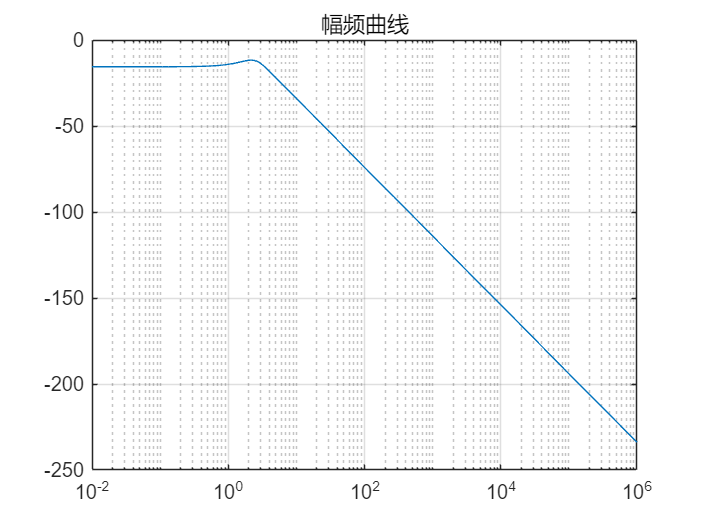

%Q1
num = [2,4];
den = [1,6,15,24];
w = logspace(-2,6,1000);
H = freqs(num,den,w);
mag = 20*log10(abs(H));

figure;
semilogx(w, mag);
grid on
title('幅频曲线')

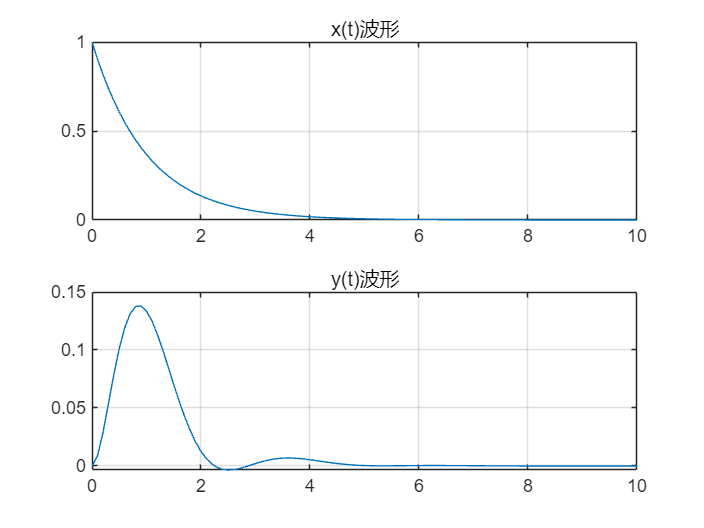

%低通特性

sys = tf(num, den);
t = 0:0.1:10;
x = exp(-t);
y = lsim(sys,x,t);

figure
subplot(2,1,1);
plot(t,x);
grid on
title('x(t)波形')

subplot(2,1,2);
plot(t,y);
grid on
title('y(t)波形')

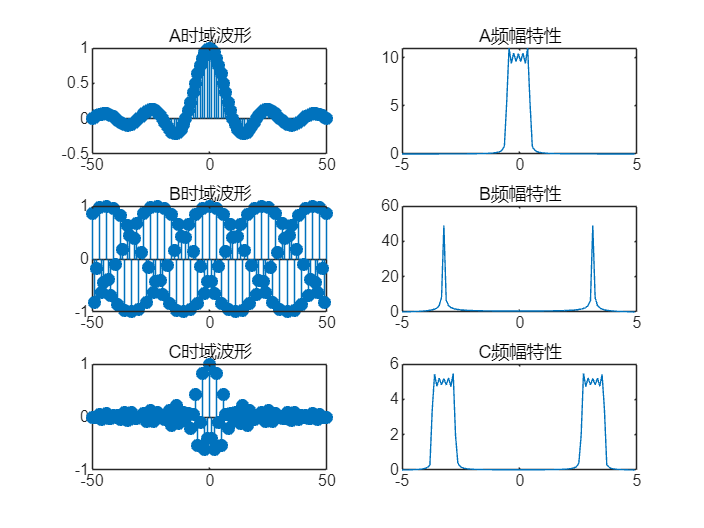

%Q2(1)
n = -50:50;
L = length(n);
x = sinc(0.1*n);
s = cos(2*n);
c = x.*s;

figure
subplot(3,2,1);
stem(n,x,"filled");
title('A时域波形');

subplot(3,2,2);
X = fftshift(fft(x));
f = (-L/2:L/2-1)*(1/(L*0.1));
plot(f,abs(X));
title('A频幅特性')


subplot(3,2,3);
stem(n,s,"filled");
title('B时域波形');

subplot(3,2,4);
S = fftshift(fft(s));
f = (-L/2:L/2-1)*(1/(L*0.1));
plot(f,abs(S));
title('B频幅特性')


subplot(3,2,5);
stem(n,c,"filled");
title('C时域波形');

subplot(3,2,6);
C = fftshift(fft(c));
f = (-L/2:L/2-1)*(1/(L*0.1));
plot(f,abs(C));
title('C频幅特性')

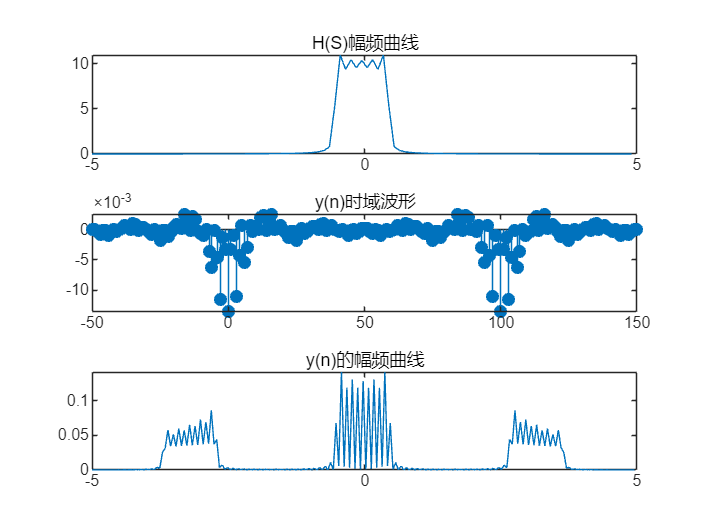


%Q2(2)
n_h = 0:100;
L_h = length(n_h);
h = sinc(0.1*(n_h-50));

figure;
subplot(3,1,1);
H = fftshift(fft(h));
f_h = (-L/2:L/2-1)*(1/(L_h*0.1));
plot(f_h,abs(H));
title('H(S)幅频曲线');

subplot(3,1,2);
y = conv(c,h);
n_y = -50:150;
L_y = length(n_y);
stem(n_y,y,"filled");
title('y(n)时域波形');

subplot(3,1,3);
Y = fftshift(fft(y));
f_y = (-L_y/2:L_y/2 - 1)*(1/(L_y*0.1));
plot(f_y,abs(Y));
title('y(n)的幅频曲线');


%Q2(3)
%H(s)是低通滤波器，y(n)是C通过低通滤波器后的信号